# RESIDUAL RECOVERY ALGORITHM FOR MODULO SAMPLING 

## Generating Signal

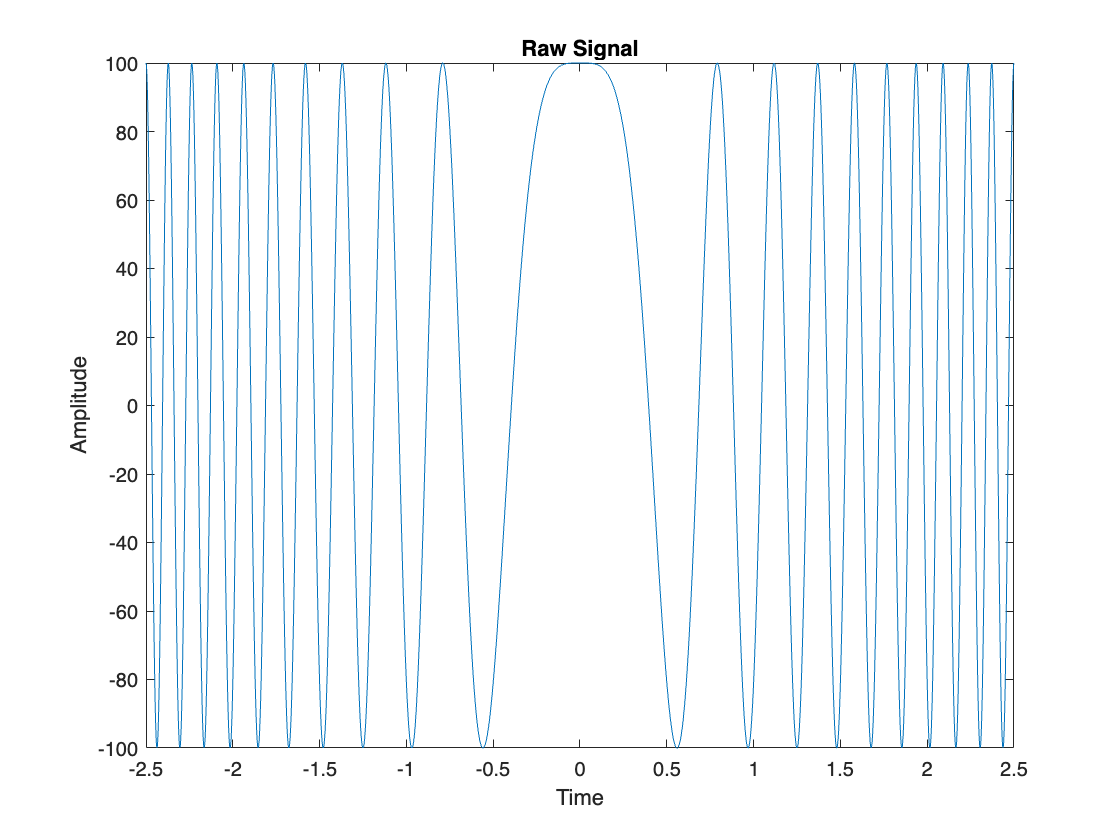

T = 5;
B = 8; % the generated signal has bandwidth wm = 16; nyquist rate = 2*w_m = 32
Fs = 500; % rate
t = linspace(-T/2, T/2, Fs*T);
f = linspace(-B/2, B/2, Fs*T);
y_raw = 100*cos(2*pi*f.*t);
plot(t, y_raw)
title("Raw Signal");
xlabel("Time");
ylabel("Amplitude")

## Fast Fourier Transform Algorithm

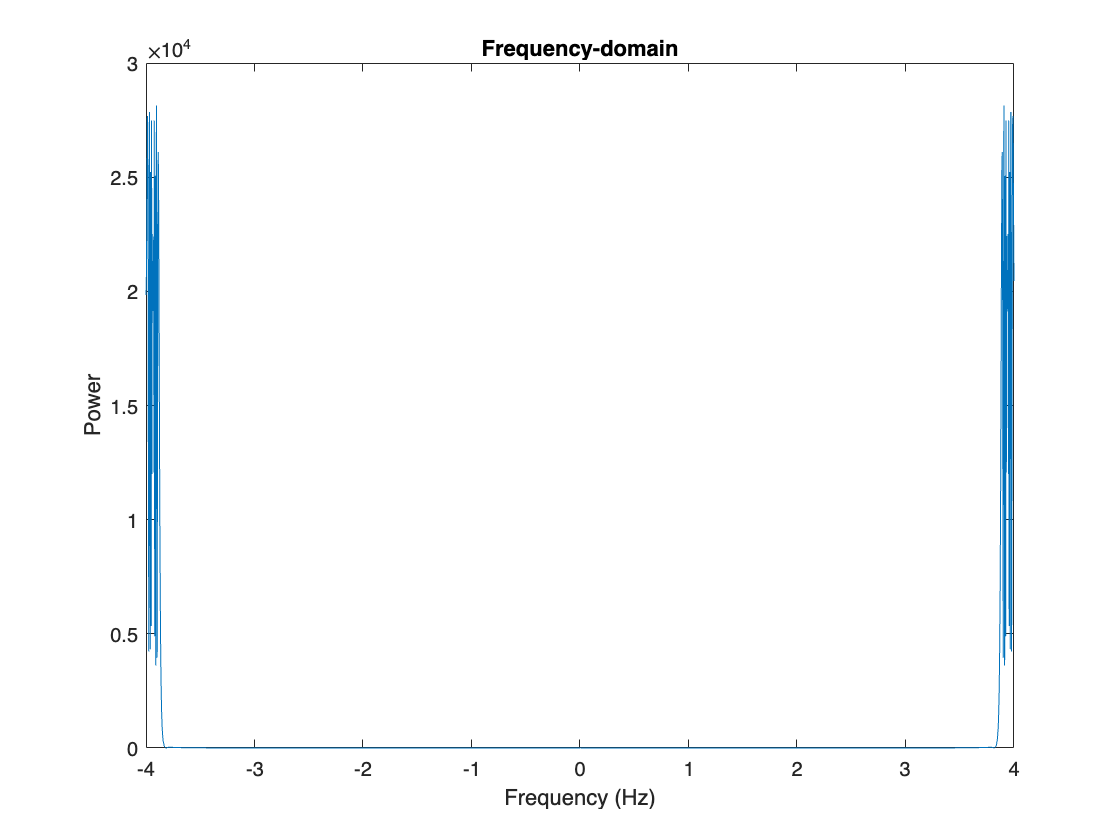

y_freq = fft(y_raw);
plot(f, abs(y_freq))
xlabel('Frequency (Hz)')
ylabel('Power')
title('Frequency-domain')

## Shift the curve                     

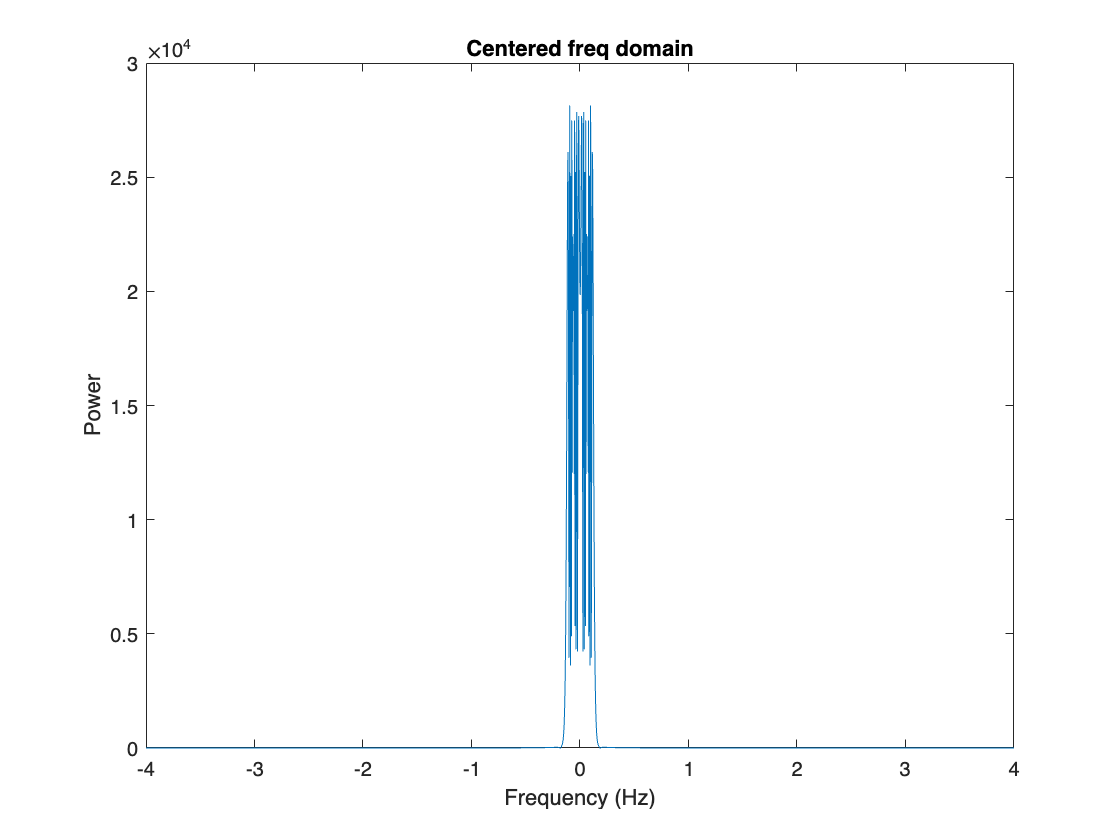

yshift = fftshift(y_freq);
plot(f,abs(yshift));
xlabel('Frequency (Hz)');
ylabel('Power');
title("Centered freq domain");

## Modulo Operator

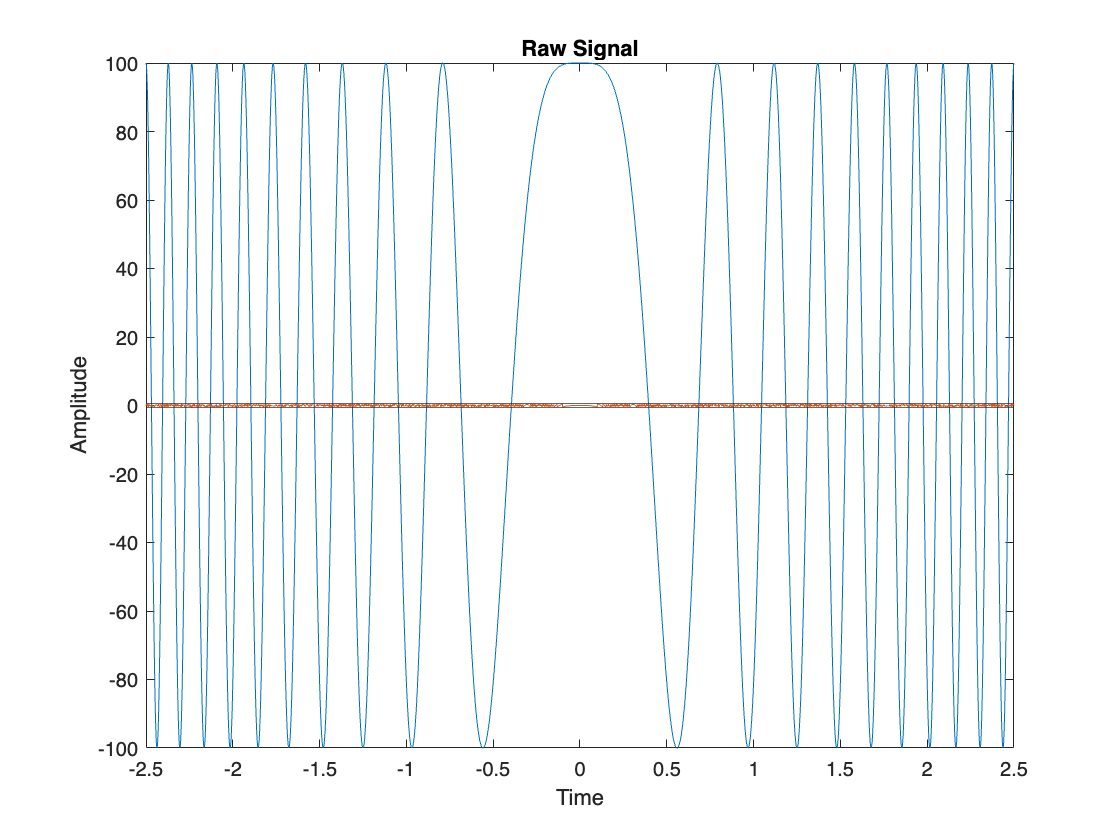

lambda = 0.5;
plot(t, y_raw)
title("Raw Signal");
xlabel("Time");
ylabel("Amplitude")
hold on;
yline(lambda);
yline(-lambda);
y_mod = mod(y_raw + lambda, 2*lambda) - lambda;
plot(t, y_mod);
hold off


wm = 16 %bandwidth

wm = 16

OF = 10 % oversampling factor

OF = 10

ws = 2*wm*OF; % sampling rate
Ts = 2*pi/ws; % sampling interval
n = -floor(T/(2*Ts)):floor(T/(2*Ts));
nTs = n.*Ts; % time of sampling points
nfs = nTs.*2*B/T; % the real frequency for the sampling point
f_lambda = mod(100*cos(2*pi*nfs.*nTs), 2*lambda) - lambda; %M_lambda(f(nT_s))
f_lambda(f_lambda > lambda) %check whether there is value larger than lambda: empty


ans =

  1×0 empty double row vector



z_true = 100*cos(2*pi*nfs.*nTs) - f_lambda;



N = length(n) % total number of samples in time domain

N = 255

FR = ws/N; % FR = w_max/SL = (w_s/2)/(N/2) = w_s/N
nws = nTs*ws/T; % the range of the spectrum plot w.r.t w_s

## Add Noises

SNR = 25; %set as in article
N = length(n);
sigma_noise = sqrt(((norm(f_lambda))^2/N)/exp(SNR/10));
noise = sigma_noise * randn(1, N);
f_lambda_withnoise = f_lambda + noise;


m = 1e5

m = 100000

rho = linspace(wm, ws/2, m);
N_lambda = 128;
DTFT_z0 = DTFT_pinverse(f_lambda, rho, nTs, Ts);



z_0 = project_Sn(DTFT_z0, N_lambda);
plot(nTs, z_0)

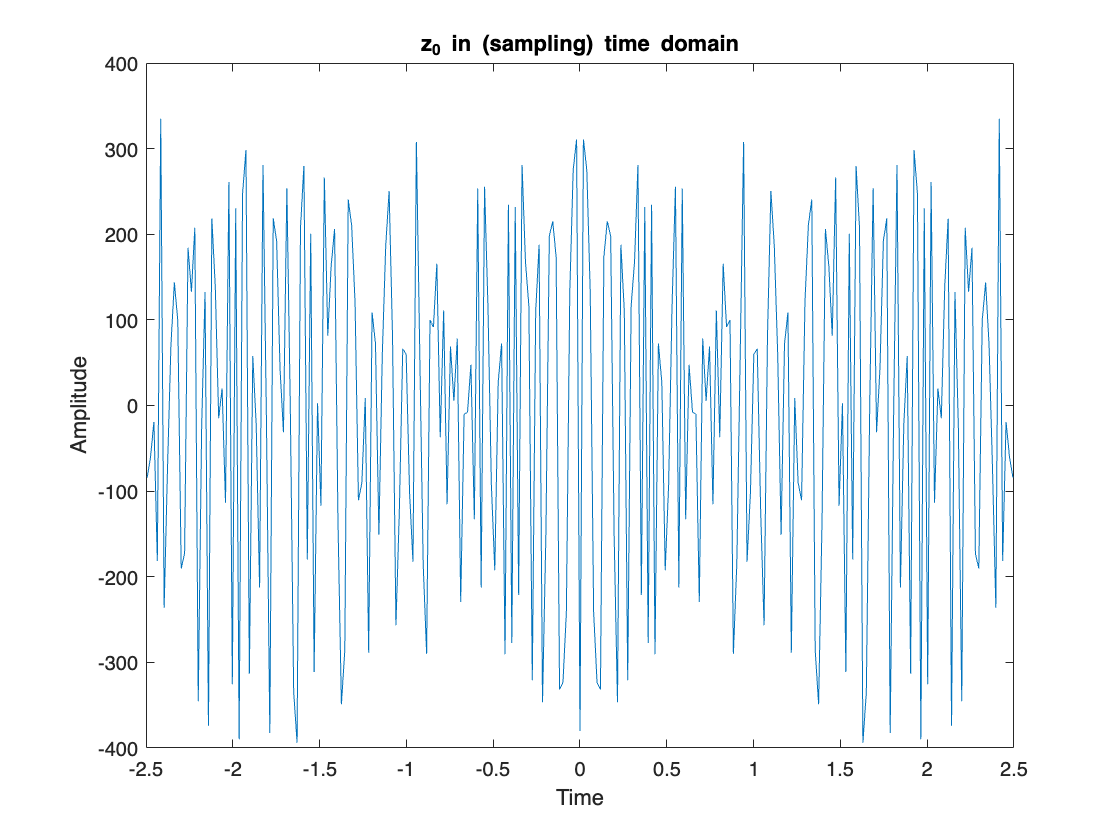

title("z_0 in (sampling) time domain");
xlabel("Time");
ylabel("Amplitude")

%Test z_0: check for frequency > w_m
z_0_freq = fft(z_0)

z_0_freq = 1.0e+03 *

  -0.3156 - 0.0000i  -0.3162 - 0.0039i  -0.3182 - 0.0078i  -0.3216 - 0.0119i  -0.3266 - 0.0161i  -0.3334 - 0.0206i  -0.3426 - 0.0254i  -0.3549 - 0.0307i  -0.3715 - 0.0367i  -0.3946 - 0.0439i  -0.4292 - 0.0531i  -0.4877 - 0.0665i  -0.6190 - 0.0922i  -1.4657 - 0.2368i   1.7492 + 0.3047i  -0.5560 - 0.1039i  -1.0712 - 0.2139i  -3.9149 - 0.8321i   2.3140 + 0.5217i  -1.1473 - 0.2736i   1.0837 + 0.2726i   1.0265 + 0.2717i  -1.5542 - 0.4319i  -1.0359 - 0.3017i   0.4990 + 0.1520i   0.5628 + 0.1790i   3.5338 + 1.1723i  -3.9523 - 1.3654i   1.2749 + 0.4581i  -1.0899 - 0.4068i  -0.5764 - 0.2233i  -7.1579 - 2.8749i   2.9739 + 1.2372i   3.1195 + 1.3431i   2.1166 + 0.9424i  -4.0616 - 1.8686i   0.4933 + 0.2344i   1.8307 + 0.8976i   4.2480 + 2.1480i   3.3148 + 1.7277i  -5.1042 - 2.7409i  -2.4245 - 1.3407i   0.0768 + 0.0437i   2.9870 + 1.7492i  -2.5195 - 1.5174i  -0.1518 - 0.0940i  -3.0123 - 1.9169i  -0.3997 - 0.2613i  -4.3941 - 2.9508i  -0.6978 - 0.4812i


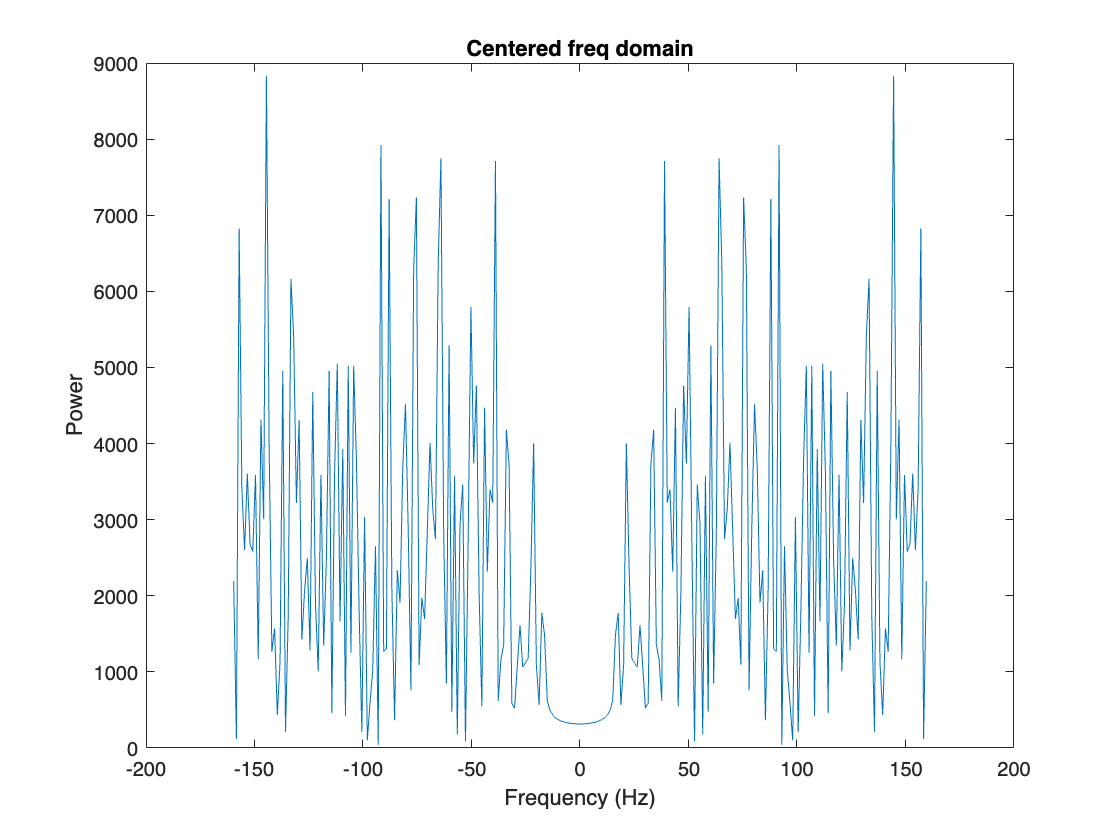

z_0_shift = fftshift(z_0_freq); %center the plot around 0;
plot(nws,abs(z_0_shift));
xlabel('Frequency (Hz)');
ylabel('Power');
title("Centered freq domain");

% recovery in noise-free case
f_recovery = B2R2(lambda, f_lambda, wm, ws, N_lambda, m, Ts, nTs, z_true); %without noise
plot(nTs, f_recovery)
hold on
plot(nTs, cos(2*pi*nfs.*nTs))
hold off

% Check
gradient1 = DTFT_pinverse(z_0 - f_lambda, rho, nTs, Ts);
obj_value1 = obj(z_0, f_lambda, rho, nTs);
obj_value2 = obj(z_0 - 10.*gradient1, f_lambda, rho, nTs);


%recovery in noisy case
f_recovery = B2R2(lambda, f_lambda_withnoise, wm, ws, N_lambda, m, Ts, nTs, z_true); %without noise
plot(nTs, f_recovery)
hold on
plot(nTs, cos(2*pi*nfs.*nTs))
hold off

function f = B2R2(lambda, f_lambda, w_m, w_s, N_lambda, m, Ts, nTs, z_true)
    
    rho = linspace(w_m, w_s/2, m);

    f_lambda_hat = f_lambda;
    DTFT_z0 = DTFT_pinverse(f_lambda, rho, nTs, Ts);
    z_0 = project_Sn(DTFT_z0, N_lambda);
    residue_0 = z_0 - z_true;
    
    while N_lambda > 0
        z = z_0;
        objective_val = obj(z_0, f_lambda, rho, nTs);
        objective_old_val = 2*objective_val;
        
        while (objective_old_val - objective_val)/objective_old_val >= 0.05
            objective_old_val = objective_val;
            gradient = DTFT_pinverse(z - f_lambda_hat, rho, nTs, Ts);
            gamma = 10;
            gamma = backtr(gamma, z, gradient, @obj, f_lambda, rho, nTs);
            y = z - gamma.* gradient;
            objective_val = obj(y, f_lambda, rho, nTs);
            z = project_Sn(y, N_lambda);
            objective_val = obj(z, f_lambda, rho, nTs);
            residue = z_true - z_0;
        end
        z_hat = z;
        z_hat_round = ceil(floor(z_hat/lambda)/2);
        f_lambda_hat = f_lambda_hat - z_hat;
        N_lambda = N_lambda - 1;
        z_0 = project_Sn(z_hat_round, N_lambda);
        residue = z_true - z_0;
    end

    f = f_lambda_hat;

end

% The inverse partial DTFT function
function inverse = DTFT_pinverse(f_lambda, rho, nTs, Ts)
    supp = cat(2, -rho, rho); %dim = 2, rho is one-sided
    F_rho = exp(-(1i).*transpose(supp)*nTs); %m*n
    F_rho_f = F_rho*transpose(f_lambda); %m*1
    F_rho_star = exp((1i).*transpose(nTs)*supp); %n*m
    F_rho_star_f = F_rho_star*F_rho_f; %n*1
    inverse = transpose((Ts/(2*pi)).*F_rho_star_f); %1*n
end


% The S_{N} projection function
function projected = project_Sn(z, N_lambda)
    n = length(z); %y must be odd
    for i = 1:n
        if abs(i - (n + 1)/2) > N_lambda
            z(i) = 0;
        end
    end
    projected = z;
end


% backtracking line search
function [alpha] = backtr(alpha_guess,Xk,dk,F, f_lambda, rho, nTs) %alpha_guess > 0
    
    delta = 0.5;
    
    % Try (-) direction
    alpha = alpha_guess;
    LHS1 = F(Xk, f_lambda, rho, nTs) - F(Xk - alpha.*dk, f_lambda, rho, nTs);
    RHS1 = delta * alpha * norm(dk)^2;
    while (F(Xk, f_lambda, rho, nTs) - F(Xk - alpha.*dk, f_lambda, rho, nTs) < delta * alpha * norm(dk)^2) 
        
        if alpha <= 1e-4
            alpha = 0;
            break
        else 
            alpha = delta*alpha;
        end
        LHS1 = F(Xk, f_lambda, rho, nTs) - F(Xk - alpha.*dk, f_lambda, rho, nTs);
        RHS1 = delta * alpha * norm(dk)^2;
    end
    alpha1 = alpha;
    F1 = F(Xk - alpha1.*dk, f_lambda, rho, nTs);
    
    % Try (+) direction
    alpha = alpha_guess;
    LHS2 = F(Xk, f_lambda, rho, nTs) - F(Xk + alpha.*dk, f_lambda, rho, nTs);
    RHS2 = delta * alpha * norm(dk)^2;
    while (F(Xk, f_lambda, rho, nTs) - F(Xk + alpha.*dk, f_lambda, rho, nTs) < delta * alpha * norm(dk)^2)
        LHS2 = F(Xk, f_lambda, rho, nTs) - F(Xk + alpha.*dk, f_lambda, rho, nTs);
        RHS2 = delta * alpha * norm(dk)^2;
        if alpha <= 1e-4
            alpha = 0;
            break
        else 
            alpha = delta*alpha;
        end
    end
    alpha2 = alpha;
    F2 = F(Xk + alpha2.*dk, f_lambda, rho, nTs);

    if F1 > F2
        alpha = -alpha2; %because in B2R2 we minus gamma
    else
        alpha = alpha1;
    end
    
end


% Objective function
function objective = obj(z, f_lambda, rho, nTs)
    supp = cat(2, -rho, rho); % dim = 2 for raw contactation, rho is one-sided
    F_rho = exp(-(1i).*transpose(supp)*nTs); % m*n
    diff = F_rho*transpose(f_lambda) - F_rho*transpose(z); %n*1
    objective = 0.5*norm(diff)^2;
end